# Solve 6-dof equations of motion:

In this script we're going to see how we can **numerically** solve the 6-DOF equations of motion for a rigid body.  We'll approach this task from three different angles:

- We'll see how to write our own ODE solver using the classic "Runge Kutta" algorithm that is typically introduced in 2nd year Numerical methods classes.

- We'll see how to use one of MATLAB's built in ODE solvers called `ode45()`

- We'll see how to use Simulink to solve the 6-DOF system

Recall that our 6-DOF equations of motion are composed of or 3 translational equations of motion, and 3 angular equations of motion.  We represent these equations as:


$$^BF = m.(\enspace ^B\dot{v}  \enspace + \enspace
{^B\omega} \times {^Bv} \enspace)$$



$$^BM = {^BI}. ^B\dot{\omega}  \enspace + \enspace
{^B\omega} \times ({^BI \thinspace. \thinspace ^B\omega}) \enspace$$


where $^BX$ means that the components of $X$ are expressed in the vehicles body fixed frame.  To convert the body rates $^B\omega$ into Euler rates we'll use the following rotation sequence:

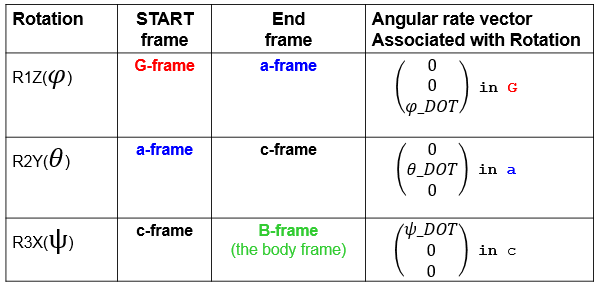

NOTE: a slightly more descriptive and verbose nomenclature for our 6-DOF equations of motion would be the following:


$$^BF = m.(\enspace ^B_-\dot{v}_C  \enspace + \enspace
{^B_G\omega_B} \times {^B_Gv_C} \enspace)$$



$$^BM = {^BI} \thinspace . ^B_-\dot{\omega}_B  \enspace + \enspace
{^B_G\omega_B} \times ({^BI \thinspace. \thinspace ^B_G\omega_B}) \enspace$$


where:

$\matrix{

\bullet & {^B_Gv_C}  
}$    :    A vector representing the vehicles ***velocity*** of the  centre of mass C.  The vector is expressed in components of the B-frame.  The G subscript indicates that the "measurement" of the velocity is as seen by the G-frame. 

$\matrix{
\bullet & ^B_-\dot{v}_C = \enspace 
_B\pmatrix{
\frac{d \enspace ^B_Gv_C}{dt}
}
}$    :    the derivative of $^B_Gv_C$ as seen by the B-frame, and expressed in components of the B-frame.  So if we integrate $^B_-\dot{v}_C$, then we'll get $^B_Gv_C$.

$\matrix{

\bullet & {^B_G\omega_B}  
}$   :    the angular ***velocity*** of the B-frame as observed by the G-frame, and expressed in components of the B-frame.

$\matrix{
\bullet & {^B_-\dot{\omega}_B}  = \enspace

_B\pmatrix{
\frac{d \enspace ^B_G{\omega}_B}{dt}
}
}
}$   :    the derivative of  $\matrix{
{^B_G{\omega}_B}  
}$  as seen by the B-frame, and expressed in components of the B-frame.  So if we integrate $\matrix{

{^B_-\dot{\omega}_B}  
}$, then we'll get $\matrix{
{^B_G{\omega}_B}  
}$.

$\matrix{

\bullet & {^BI}  
}$      :    the Inertia of the body computed about the B-frame which is attached to the body's center of mass.

$\matrix{

\bullet 
}$    *B-frame*  :    the body fixed frame attached to the body's center of mass.

$\matrix{

\bullet 
}$    G*-frame*  :   the inertial reference frame.

$\matrix{

\bullet 
}$    A . B  :   matrix A multiplied by matrix B.

$\matrix{

\bullet & a \times b
}$    :   vector CROSS product.

`Bradley Horton : 01-Mar-2016, bradley.horton@mathworks.com.au`

## **Define vehicle Mass, Inertia and Initial Conditions**

P_veh.I = [ ...
            0.005831943165131, 0,                 0;
            0,                 0.005831943165131, 0;
            0,                 0,                 0.011188595733333;
          ]; % (kg.m^2)
       
P_veh.mass  = 0.9272;    % (kg)

% Vehicle INITIAL conditions 
P_veh.Vb_init     = [0;0;0]; % (m/sec)    Initial velocity in BODY axes
P_veh.wb_init     = [0;0;0]; % (rad/sec)  Initial body rates
P_veh.eul_init    = [0;0;0]; % (rad)      Initial EULER angles [yaw,pitch,roll]
P_veh.Xe_init     = [0;0;0]; % (m)        Initial position in INERTIAl axes

**Define Excitation Forces and Moments (in BODY frame)**

We'll stimulate our system with some forces and moments.  This stimuli is defined as a collection of time series data stored in an EXCEL file.  Let's read this data into MATLAB and plot it:

TFM_TAB = readtable('bh_some_FbMb_TS_data.xlsx', 'Sheet', 'D_short_XYZ');

Echo the first few lines of this table:

TFM_TAB(1:3,:)

ans = 3×7 table
    Time    Fb_X    Fb_Y     Fb_Z      Mb_X    Mb_Y      Mb_Z   
    ____    ____    ____    _______    ____    ____    _________

       0     0       0      -9.0958     0       0              0
    0.01     0       0       -9.083     0       0      0.0001655
    0.02     0       0      -8.9508     0       0      0.0018196


There's lots of data in this log file, so just consider the first 5 seconds

TFM_TAB = TFM_TAB( TFM_TAB.Time <= 5, : );

Plot the excitation Forces and Moments that we will apply to our vehicle:

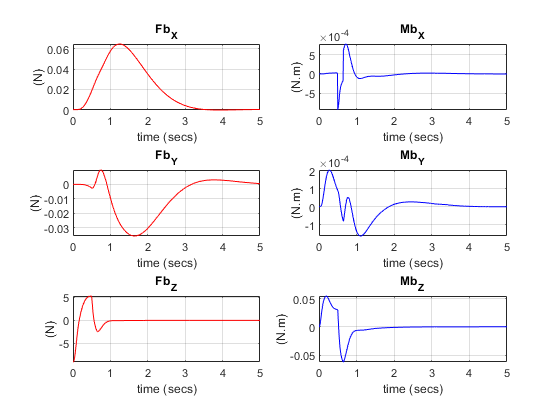

figure;
bh_plot_tfm(TFM_TAB);

## In MATLAB define the ODE system to solve:

To solve our 6-DOF system:


$$^BF = m.(\enspace ^B\dot{v}  \enspace + \enspace
{^B\omega} \times {^Bv} \enspace)$$



$$^BM = {^BI} . ^B\dot{\omega}  \enspace + \enspace
{^B\omega} \times ({^BI \thinspace. \thinspace ^B\omega}) \enspace$$


we need to write a MATLAB function that defines the "state derivatives" of the system of interest.  ie:  I need to write a MATLAB function that represents a general system:


$$\dot{\matrix{q}} = f(t,q)$$


For our system we're going to define the following 12 element state vector $\bf{q}$ and the corresponsing 12 element vector of state derivatives $\bf {\dot{q}}$:

- $\bf{q}$ = $\pmatrix{
\enspace ^Bv_x \enspace , 
\enspace ^Bv_y \enspace , 
\enspace ^Bv_z \enspace ,
\enspace ^B\omega_x \enspace ,
\enspace ^B\omega_y \enspace ,
\enspace ^B\omega_z \enspace ,
\enspace \phi \enspace ,
\enspace \theta \enspace ,
\enspace \psi \enspace ,
\enspace ^GX \enspace , 
\enspace ^GY \enspace , 
\enspace ^GZ \enspace  
}$

- $\bf {\dot{q}}$ = $\pmatrix{
\enspace ^B\dot{v}_x \enspace , 
\enspace ^B\dot{v}_y \enspace , 
\enspace ^B\dot{v}_z \enspace ,
\enspace ^B\dot{\omega}_x \enspace ,
\enspace ^B\dot{\omega}_y \enspace ,
\enspace ^B\dot{\omega}_z \enspace ,
\enspace \dot{\phi} \enspace ,
\enspace \dot{\theta} \enspace ,
\enspace \dot{\matrix{\psi}} \enspace ,
\enspace ^G\dot{X} \enspace , 
\enspace ^G\dot{Y} \enspace , 
\enspace ^G\dot{Z} \enspace  
}$

I've written a MATLAB function called `bh_the_6dof_eoms.m `that implements this.  Here are the first 36 lines of this function:

dbtype('bh_the_6dof_eoms', '1:36')

1     function qDOT = bh_the_6dof_eoms( t, q, m, I, FbMb_at_t )
2         % get the excitation Forces and Moments
3         FbMb = FbMb_at_t(t);
4         F    = FbMb(1:3);    % (N),   Body frame, Force  vector
5         M    = FbMb(4:6);    % (N.m), Body frame, Moment vector
6     
7         % extract components from the STATE vector
8         vB    = q( 1:3);   % (m/s),   Body frame, translational vel 
9         w     = q( 4:6);   % (rad/s), Body frame, angular velocity       
10        e     = q( 7:9);   % (rad),   Euler angles
11        xyzE  = q(10:12);  % (m),     INERTIAL frame, position
12    
13        %  F = m*(vDOT + w_x_v)   
14        vDOT = F/m - cross(w,vB); 
15    
16        % M  = I*wDOT + w_x_(I*w) 
17        wDOT = inv(I) * (M - cross(w, I*w)); 
18    
19        % euler rates from body rates
20        eDOT = LOC_get_eDOT(w, e); 
21    
22        % Inertial velocity
23        bRg     = LOC_get_bRg(e);
24        gRb     = bRg.'; 
25        vE      = gRb * vB;
26       

Our INITIAL state vector is:

% state vector INITIAL conditions
q_init = [ P_veh.Vb_init;
           P_veh.wb_init;
           P_veh.eul_init;
           P_veh.Xe_init   ];

**Solve our ODEs using hand written ODE solver:**

Let's focus on the general problem of:


$$\dot{\matrix{y}} = f(t,y)$$


Perhaps you want your students to explore one of the numerical methods for solving systems of ODEs.  Perhaps you want them to implement their own version of the classic "Runge-Kutta" 4th oder algorithm.  Recall that this RK4 algorithm looks like this (REF: *"*[*Numerical Computing with MATLAB*](https://au.mathworks.com/moler/tools_form.html?s_iid=accourse_cw_ac_bod)*" - Cleve Moler*):

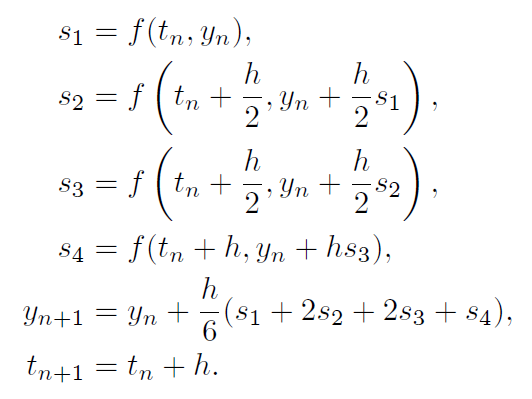

 We can implement this algorithm in MATLAB using only a few lines of code.  For example here's one implmentation:

dbtype('bh_ode4.m', '23:31')

23    function y_next = LOC_rk4(f,t,y,h)
24        s1 = f(t      ,  y);
25        s2 = f(t + h/2,  y + h*s1/2 );
26        s3 = f(t + h/2,  y + h*s2/2 );
27        s4 = f(t + h  ,  y + h*s3   );
28    
29        y_next = y +  (h/6)*( s1 + 2*s2 + 2*s3 + s4);
30    end
31    


**Solve our ODEs using hand written **RK4** ODE solver:**

So our RK4 function has been written to solve problems of the form:


$$\dot{\matrix{y}} = f(t,y)$$


and our specific 6-DOF equation of motion system is of the form:


$$\dot{\matrix{q}} = f(t,q)$$


So the pieces are all coming together:

% define OUR system that we want to solve
FM_at_t   = @(t)    bh_get_Fb_and_Mb_at_t( t, TFM_TAB );
dqdt_at_t = @(t, q) bh_the_6dof_eoms( t, q, P_veh.mass, P_veh.I, FM_at_t );

% Define some ODE solver settings
t_span = [0 5]; % (sec), [tstart, tend]
dt     = 0.01;   % (sec), fixed step size

% OK: let's use our ODE solver
[rk4_T,rk4_q]  = bh_ode4(dqdt_at_t, t_span, q_init, [], dt);

Plot the solution:

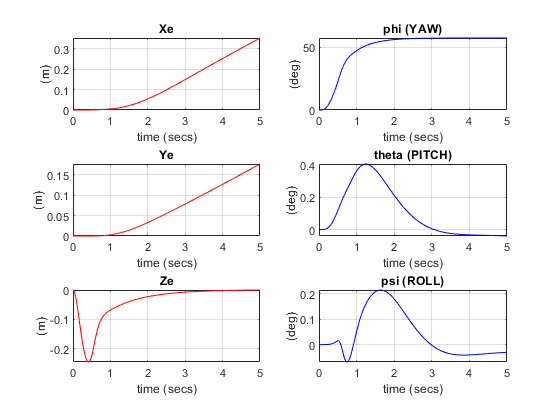

% plot our solution
figure;  bh_plot_6dof_solution(rk4_T,rk4_q)

# 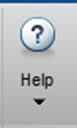 Take a moment !

If you're interested in the broad topic of Numerically solving ODEs, don't forget how useful MATLAB's HELP browser can be. As an experiment, here's a simple text search to try with the HELP Browser:

doc Ordinary Differential Equations

**Solve our ODEs using MATLAB's **`ode45()`** ODE solver:**

Perhaps you (or your students) don't want to reinvent a very round wheel.  If this is your situation, then why not consider one of MATLAB's many ODE solvers.  A good one to start with is the **ode45** solver.

% Define some ODE solver settings
t_span     = [0 5];   % (sec), [tstart, tend]
my_options = odeset('RelTol', 1e-7, 'AbsTol', 1e-7);

% OK: let's use our ODE solver
[T, Q]  = ode45(dqdt_at_t, t_span, q_init, my_options);

Plot the solution:

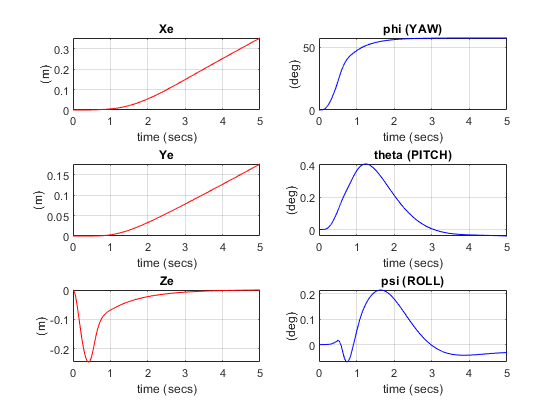

% plot our solution
figure;  bh_plot_6dof_solution(T, Q)

## But .... why not use SIMULINK ?

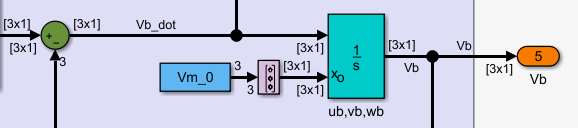

If you're interested in solving ODEs, an alternate approach to using MATLAB is to use SIMULINK.  In Simulink you express the problem using a "block diagram" language - which makes modelling systems with "feedback" very easy.   In the following model, look at how we've implemented the 6-DOF equations of motion:


$$^BF = m.(\enspace ^B\dot{v}  \enspace + \enspace
{^B\omega} \times {^Bv} \enspace)$$



$$^BM = {^BI}. ^B\dot{\omega}  \enspace + \enspace
{^B\omega} \times ({^BI \thinspace. \thinspace ^B\omega}) \enspace$$


Note that we can also define a "block's" behaviour by writing some MATLAB code - sometimes it just makes more sense to write a few lines of code.  Some good examples of this are in the subsystem for computing the Direction Cosine Matrix (DCM) ... so check that out too !

open_system('bh_6dof')

When you run the Simulink model you get the following response:

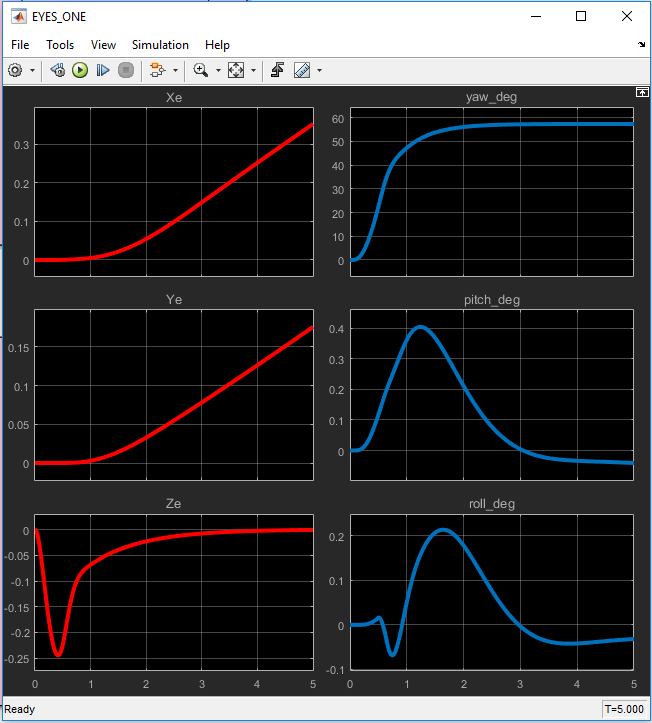

# Recall how these pieces come together in our Quadcopter model: